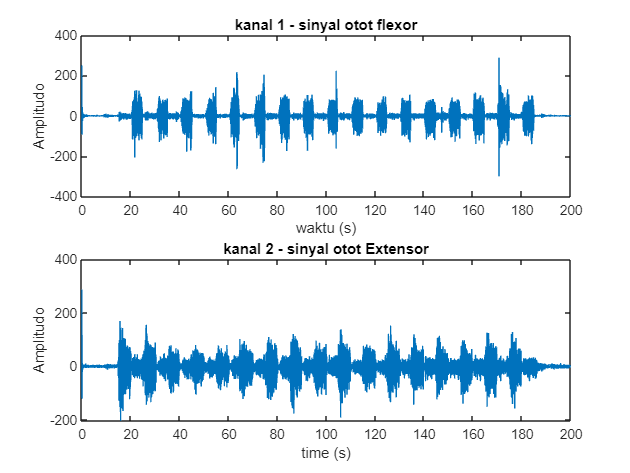

close all
clear
clc

% Load data
load subjek1a.txt
load subjek1b.txt
load subjek2a.txt
load subjek2b.txt
load subjek3a.txt
load subjek3b.txt
load subjek4a.txt
load subjek4b.txt

% Subject 1
ch1_subjek1a = subjek1a(:,3); %flexor
ch2_subjek1a = subjek1a(:,4); %extensor

ch1_subjek1b = subjek1b(:,3);
ch2_subjek1b = subjek1b(:,4);

% Properti signal
fs = 500;
ts = 1/fs;
time1a = (0:length(ch1_subjek1a)-1)/fs;      % time data subject 1a
time1b = (0:length(ch1_subjek1b)-1)/fs;      % time data subject 1b

% Plot
figure
subplot(2,1,1), plot(time1a, ch1_subjek1a), xlabel("waktu (s)"), ylabel("Amplitudo");
title("kanal 1 - sinyal otot flexor")
subplot(2,1,2), plot(time1a, ch2_subjek1a), xlabel("time (s)"), ylabel("Amplitudo");
title("kanal 2 - sinyal otot Extensor")

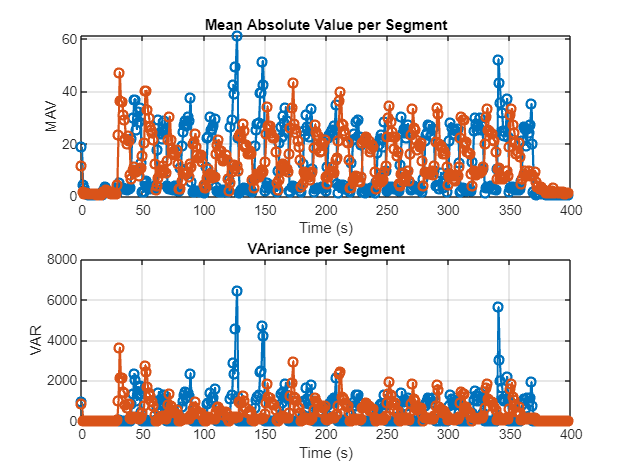

% subplot(4,1,3), plot(time1b, ch1_subjek1b), xlabel("time (s)"), ylabel("Amplitudo");
% title("chanel 1 - gerakan jari")
% subplot(4,1,4), plot(time1b, ch2_subjek1b), xlabel("time (s)"), ylabel("Amplitudo");
% title("chanel 2 - gerakan jari")
% ekstraksi fitur MAV
N_segment = round(fs*0.5); % segmentasi tiap  detik

% Segmentasi dan perhitungan MAV
L = length(ch1_subjek1a);
num_segments = floor(L / N_segment);  % jumlah segmen penuh
MAV = zeros(1, num_segments);  % preallocate
VAR = zeros(1, num_segments);  % preallocate array untuk VAR

for k = 1:num_segments
    idx_start = (k-1)*N_segment + 1;
    idx_end = k*N_segment;
    segment = ch1_subjek1a(idx_start:idx_end);
    N = length(segment);
    
    MAV(k) = mean(abs(segment));  % hitung MAV
    VAR(k) = sum(segment.^2) / (N - 1); % hitung VAR
end

% --- Plot hasil MAV ---
t_seg = (0:num_segments-1) * 1;  % waktu per segmen dalam detik

% figure;
% subplot(2,1,1), plot(t_seg, MAV, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('MAV');
% title('Mean Absolute Value per Segment'); grid on
% subplot(2,1,2), plot(t_seg, VAR, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('VAR');
% title('VAriance per Segment'); grid on
% ekstraksi fitur MAV
N_segment2 = round(fs*0.5); % segmentasi tiap  detik

% Segmentasi dan perhitungan MAV
L2 = length(ch2_subjek1a);
num_segments2 = floor(L2 / N_segment2);  % jumlah segmen penuh
MAV2 = zeros(1, num_segments2);  % preallocate
VAR2 = zeros(1, num_segments2);  % preallocate array untuk VAR

for k2 = 1:num_segments2
    idx_start2 = (k2-1)*N_segment + 1;
    idx_end2 = k2*N_segment2;
    segment2 = ch2_subjek1a(idx_start2:idx_end2);
    N2 = length(segment2);
    
    MAV2(k2) = mean(abs(segment2));  % hitung MAV
    VAR2(k2) = sum(segment2.^2) / (N2 - 1); % hitung VAR
end

% --- Plot hasil MAV ---
t_seg2 = (0:num_segments2-1) * 1;  % waktu per segmen dalam detik

figure;
subplot(2,1,1), plot(t_seg, MAV, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('MAV');
title('Mean Absolute Value per Segment'); hold on; grid on
subplot(2,1,1), plot(t_seg2, MAV2, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('MAV');
title('Mean Absolute Value per Segment'); grid on

subplot(2,1,2), plot(t_seg, VAR, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('VAR');
title('VAriance per Segment'); hold on; grid on
subplot(2,1,2), plot(t_seg2, VAR2, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('VAR');
title('VAriance per Segment'); grid on

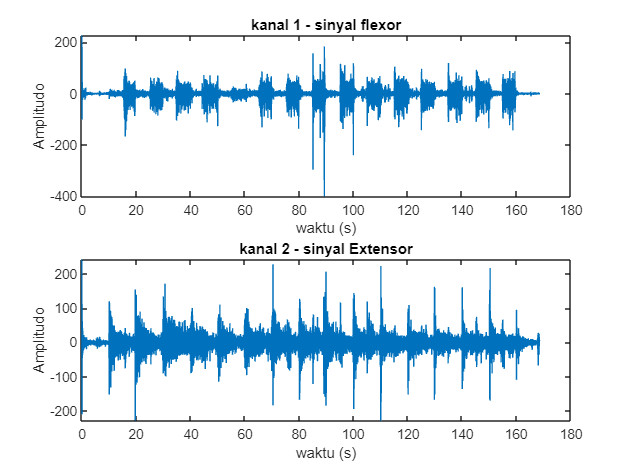

% Subject 2
ch1_subjek2a = subjek2a(:,3); %flexor
ch2_subjek2a = subjek2a(:,4); %extensor

ch1_subjek2b = subjek2b(:,3);
ch2_subjek2b = subjek2b(:,4);

% Properti signal
time2a = (1:length(ch1_subjek2a))/fs;      % time data subject 2a
time2b = (1:length(ch2_subjek2b))/fs;      % time data subject 2b

% Plot
figure
subplot(2,1,1), plot(time2a, ch1_subjek2a), xlabel("waktu (s)"), ylabel("Amplitudo");
title("kanal 1 - sinyal flexor")
subplot(2,1,2), plot(time2a, ch2_subjek2a), xlabel("waktu (s)"), ylabel("Amplitudo");
title("kanal 2 - sinyal Extensor")

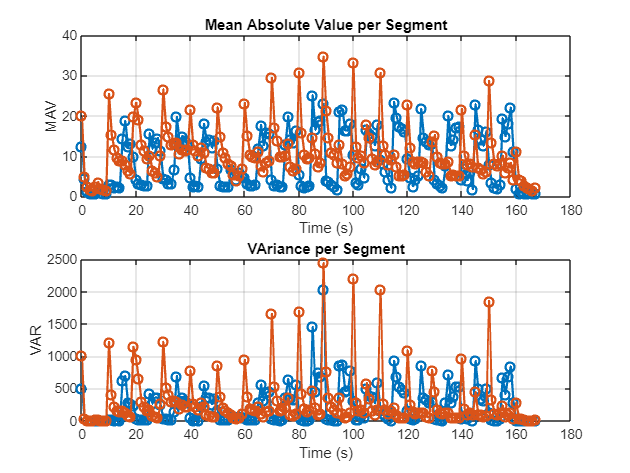

% subplot(4,1,3), plot(time2b, ch1_subjek2b), xlabel("time (s)"), ylabel("Amplitudo");
% title("chanel 1 - gerakan jari")
% subplot(4,1,4), plot(time2b, ch2_subjek2b), xlabel("time (s)"), ylabel("Amplitudo");
% title("chanel 2 - gerakan jari")
% subjek 2
% ekstraksi fitur MAV
N_segment = round(fs*1); % segmentasi tiap  detik

% Segmentasi dan perhitungan MAV
L = length(ch1_subjek2a);
num_segments = floor(L / N_segment);  % jumlah segmen penuh
MAV = zeros(1, num_segments);  % preallocate
VAR = zeros(1, num_segments);  % preallocate array untuk VAR

for k = 1:num_segments
    idx_start = (k-1)*N_segment + 1;
    idx_end = k*N_segment;
    segment = ch1_subjek2a(idx_start:idx_end);
    N = length(segment);
    
    MAV(k) = mean(abs(segment));  % hitung MAV
    VAR(k) = sum(segment.^2) / (N - 1); % hitung VAR
end

% --- Plot hasil MAV ---
t_seg = (0:num_segments-1) * 1;  % waktu per segmen dalam detik

% figure;
% subplot(2,1,1), plot(t_seg, MAV, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('MAV');
% title('Mean Absolute Value per Segment'); grid on
% subplot(2,1,2), plot(t_seg, VAR, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('VAR');
% title('VAriance per Segment'); grid on
% ekstraksi fitur MAV
N_segment2 = round(fs*1); % segmentasi tiap  detik

% Segmentasi dan perhitungan MAV
L2 = length(ch2_subjek2a);
num_segments2 = floor(L2 / N_segment2);  % jumlah segmen penuh
MAV2 = zeros(1, num_segments2);  % preallocate
VAR2 = zeros(1, num_segments2);  % preallocate array untuk VAR

for k2 = 1:num_segments2
    idx_start2 = (k2-1)*N_segment + 1;
    idx_end2 = k2*N_segment2;
    segment2 = ch2_subjek2a(idx_start2:idx_end2);
    N2 = length(segment2);
    
    MAV2(k2) = mean(abs(segment2));  % hitung MAV
    VAR2(k2) = sum(segment2.^2) / (N2 - 1); % hitung VAR
end

% --- Plot hasil MAV ---
t_seg2 = (0:num_segments2-1) * 1;  % waktu per segmen dalam detik

figure;
subplot(2,1,1), plot(t_seg, MAV, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('MAV');
title('Mean Absolute Value per Segment'); hold on; grid on
subplot(2,1,1), plot(t_seg2, MAV2, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('MAV');
title('Mean Absolute Value per Segment'); grid on

subplot(2,1,2), plot(t_seg, VAR, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('VAR');
title('VAriance per Segment'); hold on; grid on
subplot(2,1,2), plot(t_seg2, VAR2, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('VAR');
title('VAriance per Segment'); grid on

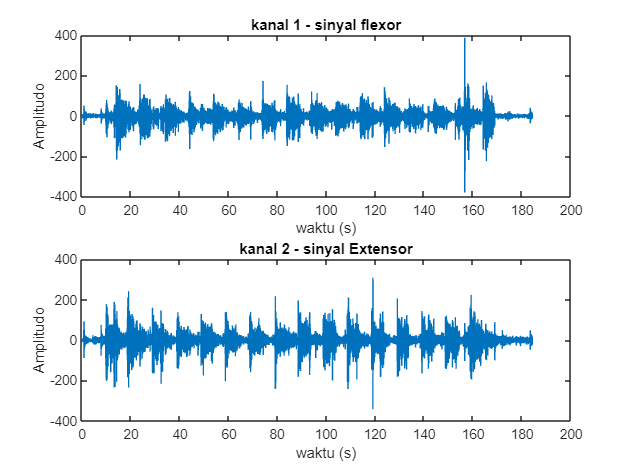

% Subject 3
ch1_subjek3a = subjek3a(:,3);
ch2_subjek3a = subjek3a(:,4);

ch1_subjek3b = subjek3b(:,3);
ch2_subjek3b = subjek3b(:,4);

% Properti signal
time3a = (1:length(ch1_subjek3a))/fs;
time3b = (1:length(ch1_subjek3b))/fs;

% plot
figure
subplot(2,1,1), plot(time3a, ch1_subjek3a), xlabel("waktu (s)"), ylabel("Amplitudo");
title("kanal 1 - sinyal flexor")
subplot(2,1,2), plot(time3a, ch2_subjek3a), xlabel("waktu (s)"), ylabel("Amplitudo");
title("kanal 2 - sinyal Extensor")

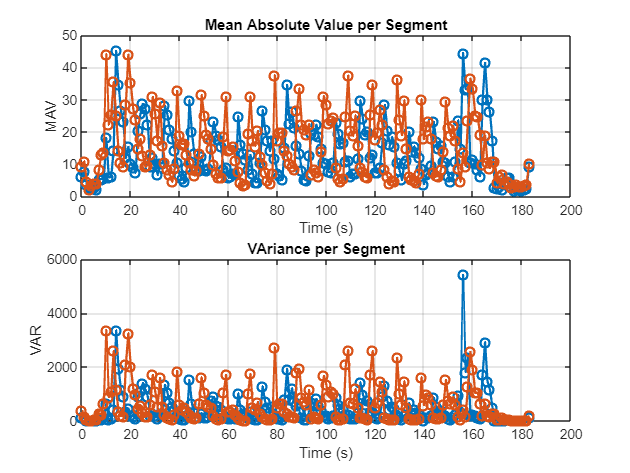

% subplot(4,1,3), plot(time3b, ch1_subjek3b), xlabel("time (s)"), ylabel("Amplitudo");
% title("chanel 1 - gerakan jari")
% subplot(4,1,4), plot(time3b, ch2_subjek3b), xlabel("time (s)"), ylabel("Amplitudo");
% title("chanel 2 - gerakan jari")
% ekstraksi fitur MAV
N_segment = round(fs*1); % segmentasi tiap  detik

% Segmentasi dan perhitungan MAV
L = length(ch1_subjek3a);
num_segments = floor(L / N_segment);  % jumlah segmen penuh
MAV = zeros(1, num_segments);  % preallocate
VAR = zeros(1, num_segments);  % preallocate array untuk VAR

for k = 1:num_segments
    idx_start = (k-1)*N_segment + 1;
    idx_end = k*N_segment;
    segment = ch1_subjek3a(idx_start:idx_end);
    N = length(segment);
    
    MAV(k) = mean(abs(segment));  % hitung MAV
    VAR(k) = sum(segment.^2) / (N - 1); % hitung VAR
end

% --- Plot hasil MAV ---
t_seg = (0:num_segments-1) * 1;  % waktu per segmen dalam detik

% figure;
% subplot(2,1,1), plot(t_seg, MAV, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('MAV');
% title('Mean Absolute Value per Segment'); grid on
% subplot(2,1,2), plot(t_seg, VAR, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('VAR');
% title('VAriance per Segment'); grid on
% ekstraksi fitur MAV
N_segment2 = round(fs*1); % segmentasi tiap  detik

% Segmentasi dan perhitungan MAV
L2 = length(ch2_subjek3a);
num_segments2 = floor(L2 / N_segment2);  % jumlah segmen penuh
MAV2 = zeros(1, num_segments2);  % preallocate
VAR2 = zeros(1, num_segments2);  % preallocate array untuk VAR

for k2 = 1:num_segments2
    idx_start2 = (k2-1)*N_segment + 1;
    idx_end2 = k2*N_segment2;
    segment2 = ch2_subjek3a(idx_start2:idx_end2);
    N2 = length(segment2);
    
    MAV2(k2) = mean(abs(segment2));  % hitung MAV
    VAR2(k2) = sum(segment2.^2) / (N2 - 1); % hitung VAR
end

% --- Plot hasil MAV ---
t_seg2 = (0:num_segments2-1) * 1;  % waktu per segmen dalam detik

figure;
subplot(2,1,1), plot(t_seg, MAV, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('MAV');
title('Mean Absolute Value per Segment'); hold on; grid on
subplot(2,1,1), plot(t_seg2, MAV2, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('MAV');
title('Mean Absolute Value per Segment'); grid on

subplot(2,1,2), plot(t_seg, VAR, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('VAR');
title('VAriance per Segment'); hold on; grid on
subplot(2,1,2), plot(t_seg2, VAR2, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('VAR');
title('VAriance per Segment'); grid on

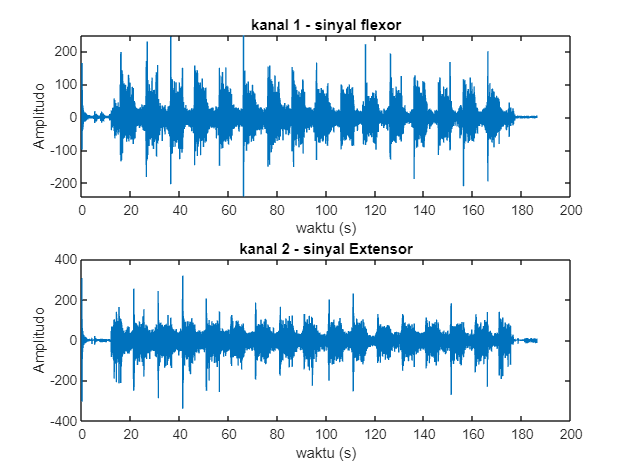

% Subject 4
ch1_subjek4a = subjek4a(:,3);
ch2_subjek4a = subjek4a(:,4);

ch1_subjek4b = subjek4b(:,3);
ch2_subjek4b = subjek4b(:,4);

% Properti signal
time4a = (1:length(ch1_subjek4a))/fs;
time4b = (1:length(ch1_subjek4b))/fs;

% plot
figure
subplot(2,1,1), plot(time4a, ch1_subjek4a), xlabel("waktu (s)"), ylabel("Amplitudo");
title("kanal 1 - sinyal flexor")
subplot(2,1,2), plot(time4a, ch2_subjek4a), xlabel("waktu (s)"), ylabel("Amplitudo");
title("kanal 2 - sinyal Extensor")

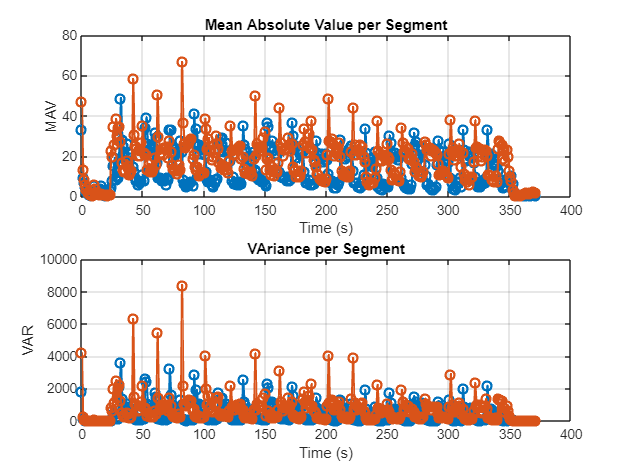

% subplot(4,1,3), plot(time4b, ch1_subjek4b), xlabel("time (s)"), ylabel("Amplitudo");
% title("chanel 1 - gerakan jari")
% subplot(4,1,4), plot(time4b, ch2_subjek4b), xlabel("time (s)"), ylabel("Amplitudo");
% title("chanel 2 - gerakan jari")
% ekstraksi fitur MAV
N_segment = round(fs*0.5); % segmentasi tiap  detik

% Segmentasi dan perhitungan MAV
L = length(ch1_subjek4a);
num_segments = floor(L / N_segment);  % jumlah segmen penuh
MAV = zeros(1, num_segments);  % preallocate
VAR = zeros(1, num_segments);  % preallocate array untuk VAR

for k = 1:num_segments
    idx_start = (k-1)*N_segment + 1;
    idx_end = k*N_segment;
    segment = ch1_subjek4a(idx_start:idx_end);
    N = length(segment);
    
    MAV(k) = mean(abs(segment));  % hitung MAV
    VAR(k) = sum(segment.^2) / (N - 1); % hitung VAR
end

t_seg = (0:num_segments-1) * 1;  % waktu per segmen dalam detik

% channel 2
N_segment2 = round(fs*0.5); % segmentasi tiap  detik

% Segmentasi dan perhitungan MAV
L2 = length(ch2_subjek4a);
num_segments2 = floor(L2 / N_segment2);  % jumlah segmen penuh
MAV2 = zeros(1, num_segments2);  % preallocate
VAR2 = zeros(1, num_segments2);  % preallocate array untuk VAR

for k2 = 1:num_segments2
    idx_start2 = (k2-1)*N_segment + 1;
    idx_end2 = k2*N_segment2;
    segment2 = ch2_subjek4a(idx_start2:idx_end2);
    N2 = length(segment2);
    
    MAV2(k2) = mean(abs(segment2));  % hitung MAV
    VAR2(k2) = sum(segment2.^2) / (N2 - 1); % hitung VAR
end

% --- Plot hasil MAV ---
t_seg2 = (0:num_segments2-1) * 1;  % waktu per segmen dalam detik

figure;
subplot(2,1,1), plot(t_seg, MAV, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('MAV');
title('Mean Absolute Value per Segment'); hold on; grid on
subplot(2,1,1), plot(t_seg2, MAV2, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('MAV');
title('Mean Absolute Value per Segment'); grid on

subplot(2,1,2), plot(t_seg, VAR, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('VAR');
title('VAriance per Segment'); hold on; grid on
subplot(2,1,2), plot(t_seg2, VAR2, '-o', 'LineWidth', 1.5), xlabel('Time (s)'), ylabel('VAR');
title('VAriance per Segment'); grid on